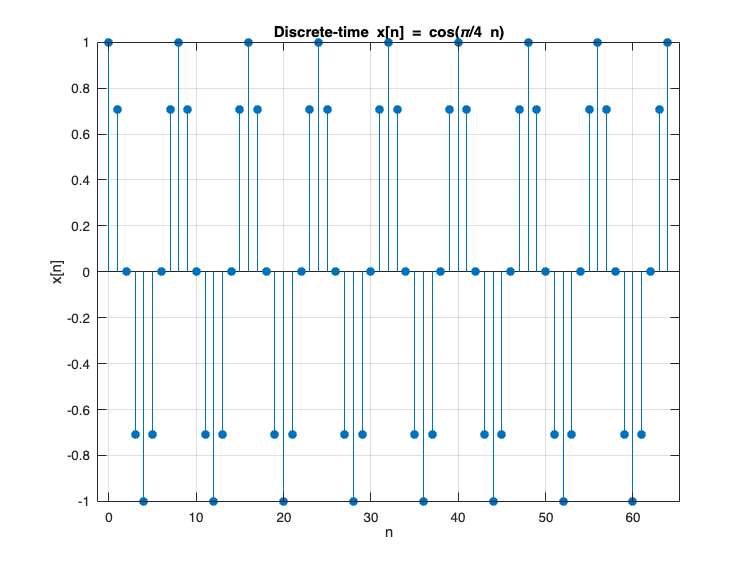

% Discrete-time signal: x[n] = cos(pi/4 * n)
omega_d = pi/4; % discrete-time freq in radians/sample
n = 0:64;       % sample indices
x_n = cos(omega_d * n);

figure;
stem(n, x_n, 'filled');
xlabel('n');
ylabel('x[n]');
title('Discrete-time x[n] = cos(\pi/4 n)');
grid on;

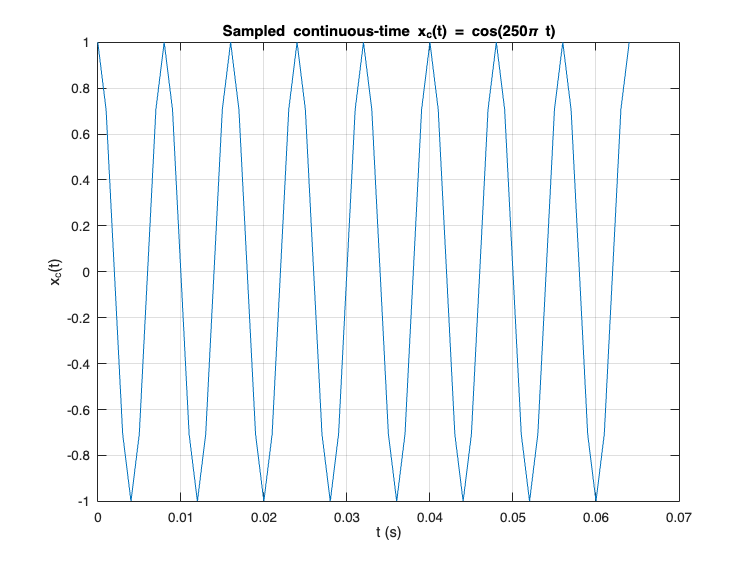


% Now, simulate continuous-time x_c(t) = cos(Omega * t)
Ts = 1/1000;        % sampling period = 1 ms
Fs = 1/Ts;          % 1000 Hz
Omega = 6250*pi;  % = 250*pi rad/s
t = n * Ts;         % actual time values
x_c = cos(Omega * t);

figure;
plot(t, x_c);
xlabel('t (s)');
ylabel('x_c(t)');
title('Sampled continuous-time x_c(t) = cos(250\pi t)');
grid on;

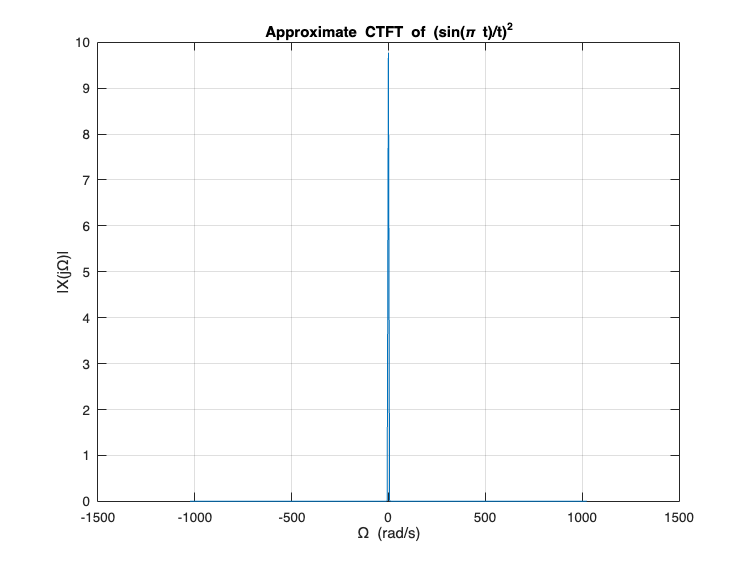

clear;

t = -10:pi/1024:10;
dt = t(2) - t(1);
x_t = (sin(pi * t)./t).^2;
x_t(t == 0) = pi^2;

N = length(x_t);
X_f = fftshift(fft(x_t)) * dt;   % scaling by dt
f = linspace(-1/(2*dt), 1/(2*dt), N);  % Hz
Omega = 2*pi*f;  % rad/s

plot(Omega, abs(X_f));
xlabel('\Omega (rad/s)');
ylabel('|X(j\Omega)|');
title('Approximate CTFT of (sin(\pi t)/t)^2');
grid on;